# Assignment 1

01.  **Plotting y(t)**

         The given signal y(t) = A*cos(2�$\pi \mathrm{ft}$)  is obtained by defining the function signal(A,f,name). 

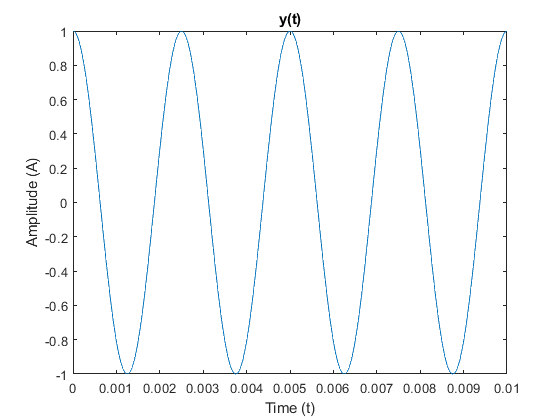

f = 400;
t = 0:0.00001:0.01;
A = 1 ;
y = A*cos(2*pi*f*t);
g1 = signal(1,f,"y(t)",0);

function g = signal(A,f,name,a,fs) % function for plotting the signal
    t = 0:0.00001:0.01;
    g = zeros(size(t));
    y = A*cos(2*pi*f*t);
    figure
    plot(t,y);
    title(name);
    xlabel('Time (t)');
    ylabel('Amplitude (A)');
    if a == 1
        hold on;
        [y1,x] = sampling(f,fs);
        stem(x,y1);
        legend('y(t)','sampled signal');
        hold off;
    end
end